folder_path = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\brain";
csv_files = dir(fullfile(folder_path, '*.csv'));
num_files = length(csv_files);
% avg = zeros([num_files, 3]); 
% pc1 = zeros([num_files, 3]);
% pc1_pct = zeros([num_files, 1]);
% pc2 = zeros([num_files, 3]);
% pc2_pct = zeros([num_files, 1]);
% pc3  = zeros([num_files, 3]);
% pc3_pct = zeros([num_files, 1]);
%silly linear regression
slopes = zeros([num_files, 3]);
Rsq = zeros([num_files, 2]); 
for i = 1:num_files
    file_path = fullfile(folder_path, csv_files(i).name);
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes(i, 1) =table2array(model1.Coefficients(2,1));
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes(i, 2) = table2array(model2.Coefficients(2,1));

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes(i, 3) = table2array(model3.Coefficients(2,1));
    Rsq(i, 1) = model1.Rsquared.Ordinary;
    Rsq(i, 2) = model2.Rsquared.Ordinary;
end
repre2 = [slopes];
dist_matri = zeros([num_files, num_files]);

for i = 1:num_files
    for j = 1:num_files
        distance = norm(repre2(i, :) - repre2(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

%load rgc axons and color linear regression
folder_path_b = "H:\Data_connectome\trace_pipe_DJ\4111\exported_color\retina";
csv_files_b = dir(fullfile(folder_path_b, '*.csv'));
num_files_b = length(csv_files_b);
slopes_b = zeros([num_files_b, 3]);
Rsq_b = zeros([num_files_b, 2]); 
for i = 1:num_files_b
    file_path = fullfile(folder_path_b, csv_files_b(i).name);
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes_b(i, 1) =table2array(model1.Coefficients(2,1));
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes_b(i, 2) = table2array(model2.Coefficients(2,1));

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes_b(i, 3) = table2array(model3.Coefficients(2,1));
    Rsq(i, 1) = model1.Rsquared.Ordinary;
    Rsq(i, 2) = model2.Rsquared.Ordinary;
end
repre3 = [slopes_b];
dist_matri = zeros([num_files_b, num_files_b]);
for i = 1:num_files_b
    for j = 1:num_files_b
        distance = norm(repre3(i, :) - repre3(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

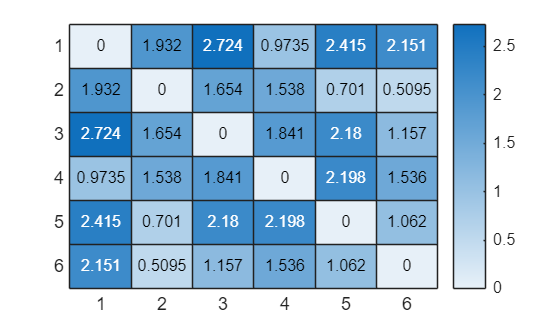

totalrepre_raw = [repre2;

    repre3];
dist_matri = zeros([height(totalrepre_raw), height(totalrepre_raw)]);
for i = 1:height(totalrepre_raw)
    for j = 1:height(totalrepre_raw)
        distance = norm(totalrepre_raw(i, :) - totalrepre_raw(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

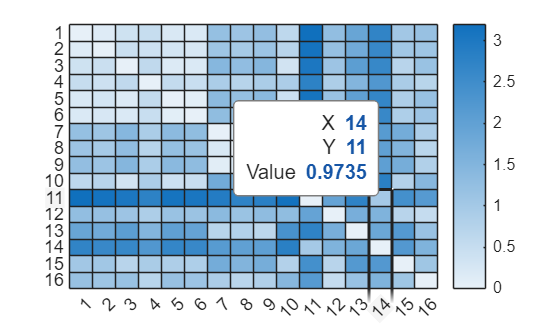

%visualize total
figure;

hold on;
log_rgc = log(repre3);
log_axon = log(repre2);
scatter3(log_rgc(:, 1), log_rgc(:, 2), log_rgc(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(repre3)
    text(log_rgc(i, 1), log_rgc(i, 2),log_rgc(i, 3),...
        num2str(i));
end
scatter3(log_axon(:, 1), log_axon(:, 2), log_axon(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(repre2)
    text(log_axon(j, 1),log_axon(j, 2), log_axon(j, 3), ...
        num2str(j));
end
grid on;
hold off;

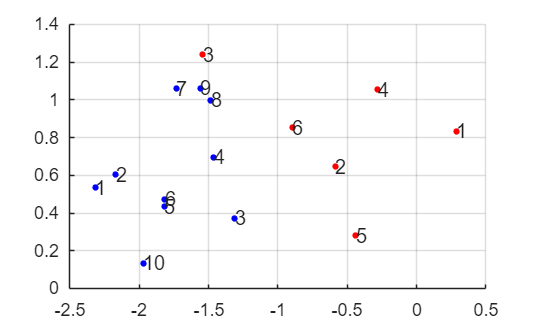

%fitting idea: constant shift in the log space 
axon_grouping = {[1,2], [5, 6], [7, 8, 9]};
mean_axons = zeros([numel(axon_grouping), 3]);

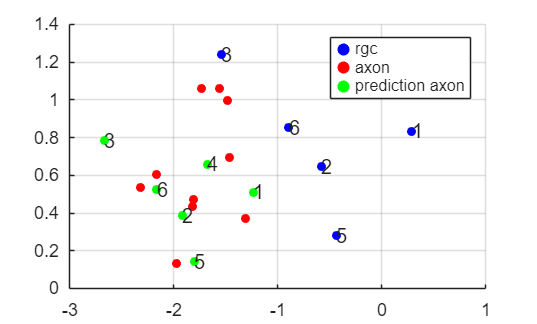

for i = 1:numel(axon_grouping)
    indx = axon_grouping{i};
    mean_axons(i, :) = mean(repre2(indx, :), 1);
end

sorted_axons = [mean_axons(1, :);
    repre2(3, :);
    repre2(4, :);
    mean_axons(2, :);
    repre2(10, :)];
logso_axons = log(sorted_axons);

sorted_rgcs = [repre3(6, :);
    repre3(1, :);
    repre3(4, :);
    repre3(2, :); ...
    repre3(5, :)];
logso_rgcs = log(sorted_rgcs);

params = zeros(2, 3);  % [a; b] for each component
r_slopes = transpose(logso_rgcs);
a_slopes = transpose(logso_axons);

for comp = 1:3
    x = r_slopes(comp, :)';   % 5x1
    y = a_slopes(comp, :)';   % 5x1
    M = [x, ones(5,1)];       % 5x2 design matrix
    params(:, comp) = M \ y;  % [a; b] for this component
end

a = params(1, :);  % [a1, a2, a3]
b = params(2, :);  % [b1, b2, b3]

% project back
prediction = a.*log_rgc + b;
figure;
hold on;
scatter3(log_rgc(:, 1), log_rgc(:, 2), log_rgc(:, 3), 20, 'blue', 'filled');
for i = 1:height(repre3)
    text(log_rgc(i, 1), log_rgc(i, 2),log_rgc(i, 3),...
        num2str(i));
end

scatter3(log_axon(:, 1), log_axon(:, 2), log_axon(:, 3), 20, 'red', 'filled');
scatter3(prediction(:, 1), prediction(:, 2), prediction(:, 3), 20, 'green', 'filled');
for i = 1:height(repre3)
    text(prediction(i, 1), prediction(i, 2),prediction(i, 3),...
        num2str(i));
end
labels = {'rgc', 'axon', 'prediction axon'};
legend(labels);
grid on;
hold off;

% log_dis = zeros([height(sorted_axons), 3]);
% for i = 1:height(log_dis)
%     log_dis(i, :) = logso_rgcs(i, :) - logso_axons(i, :);

% end
% mean_logdis = mean(log_dis, 1);
% coef_log = std(log_dis, 0, 1)./mean_logdis;

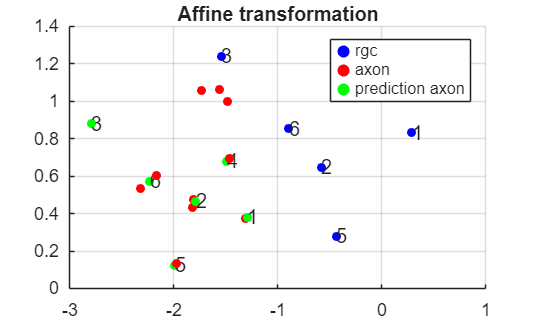

%affine transformation on log space
%sort data first
axon_grouping = {[1,2], [5, 6], [7, 8, 9]};
mean_axons = zeros([numel(axon_grouping), 3]);
for i = 1:numel(axon_grouping)
    indx = axon_grouping{i};
    mean_axons(i, :) = mean(repre2(indx, :), 1);
end

sorted_axons = [mean_axons(1, :);
    repre2(3, :);
    repre2(4, :);
    mean_axons(2, :);
    repre2(10, :)];
logso_axons = transpose(log(sorted_axons));

sorted_rgcs = [repre3(6, :);
    repre3(1, :);
    repre3(4, :);
    repre3(2, :); ...
    repre3(5, :)];
logso_rgcs = transpose(log(sorted_rgcs));

% augment RGC slopes with a row of ones
R_aug = [logso_rgcs; ones(1,5)];   % 4x5
% solve: A_aug * R_aug = a_slopes
A_aug = logso_axons / R_aug;        % 3x4, least-squares right-divide

% extract A and b
A = A_aug(:, 1:3);   % 3x3
b = A_aug(:, 4);     % 3x1

% apply to new RGC
a_predicted = A * transpose(log_rgc) + b;
a_predicted = transpose(a_predicted);

%plot this
figure;
hold on;
scatter3(log_rgc(:, 1), log_rgc(:, 2), log_rgc(:, 3), 20, 'blue', 'filled');
for i = 1:height(repre3)
    text(log_rgc(i, 1), log_rgc(i, 2),log_rgc(i, 3),...
        num2str(i));
end

scatter3(log_axon(:, 1), log_axon(:, 2), log_axon(:, 3), 20, 'red', 'filled');
scatter3(a_predicted(:, 1),a_predicted(:, 2), a_predicted(:, 3), 20, 'green', 'filled');
for i = 1:height(repre3)
    text(a_predicted(i, 1), a_predicted(i, 2),a_predicted(i, 3),...
        num2str(i));
end
labels = {'rgc', 'axon', 'prediction axon'};
legend(labels);
title('Affine transformation')
grid on;
hold off;

%now do the ratio transformation between axon and rgc
M = [1 0; -1 1; 0 1];
astar1 = repre2(1, :);
astar2 = repre2(2, :);
log_axon = (log(astar1) + log(astar2))/2;
rstar = repre3(3,  :);
log_rgc = log(rstar);
d = transpose(log_axon - log_rgc);

gamma = M\d;
residual = d - M*gamma;
relative_resi = norm(residual)/norm(d);
disp(relative_resi)

    0.1085



d_fit = M*gamma;
log_rgc_all = log(repre3);
logaxon_fitall = zeros([num_files_b, 3]);
for i = 1:height(logaxon_fitall)
    logaxon_fitall(i, :) = log_rgc_all(i, :) + transpose(d_fit);
end

axon_fitall = exp(logaxon_fitall);
disp(axon_fitall);

    0.7244    1.2871    0.9728
    0.3027    1.0682    0.4478
    0.1162    1.9341    0.3040
    0.4106    1.6051    0.8085
    0.3502    0.7398    0.3343
    0.2214    1.3123    0.3819



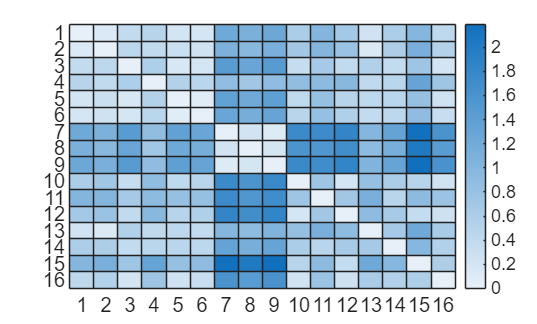

%now combine the imagened axons and real axons
real_deduced_axons = [repre2; axon_fitall];
total_num = num_files + num_files_b;
moment_of_truth = zeros([total_num, total_num]);
for i = 1:total_num
    for j = 1:total_num
        moment_of_truth(i, j) = norm(real_deduced_axons(i, :)- real_deduced_axons(j, :));
    end
end
figure;
heatmap(moment_of_truth);

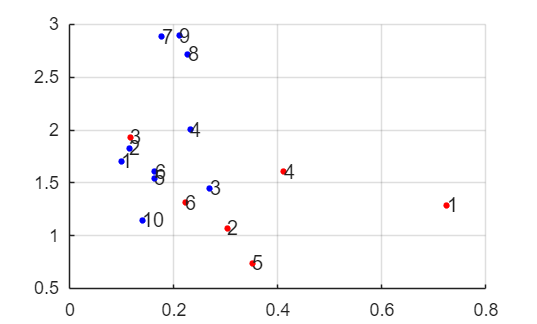

% plot the transformation and axon repre in the same figure
figure;
hold on;

scatter3(axon_fitall(:, 1), axon_fitall(:, 2), axon_fitall(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(axon_fitall)
    text(axon_fitall(i, 1), axon_fitall(i, 2), axon_fitall(i, 3),...
        num2str(i));
end
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(repre2)
    text(repre2(j, 1), repre2(j, 2), repre2(j, 3), num2str(j));
end
grid on;
hold off;

%try another transformation-- linear 3x3
axon_grouping = {[1,2], [5, 6], [7, 8, 9]};
mean_axons = zeros([numel(axon_grouping), 3]);
for i = 1:numel(axon_grouping)
    indx = axon_grouping{i};
    mean_axons(i, :) = mean(repre2(indx, :), 1);
end

%repackage axons
sorted_axons = [repre2(4, :);
    mean_axons(2, :);
    repre2(10, :);
    mean_axons(1, :);
    repre2(3, :)];
sorted_axons = transpose(sorted_axons);

%repackage rgcs for tentative matching
sorted_rgcs = [repre3(4, :);
    repre3(2, :);
    repre3(5, :);
    repre3(6, :);
    repre3(1, :)];
sorted_rgcs = transpose(sorted_rgcs);

L_R = log(sorted_rgcs);   % 3 x K
L_A = log(sorted_axons);   % 3 x K

A = L_A / L_R;         % MATLAB's built-in right-divide does the least-squares fit
                       % equivalent to L_A * pinv(L_R)

% check the residual
L_A_predicted = A * L_R;
residual = L_A - L_A_predicted;
fprintf('residual norm per pair: %.3f\n', norm(residual, 'fro') / sqrt(size(L_R, 2)));

residual norm per pair: 0.450


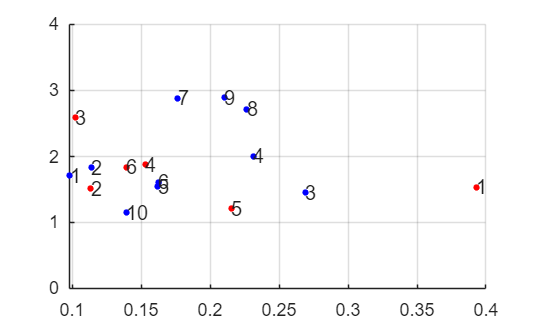

log_allrgcs = log(transpose(repre3));
log_a_predicted_new = exp(A * log_allrgcs);
a_predicted_new = transpose(log_a_predicted_new);
figure;
hold on;

scatter3(a_predicted_new(:, 1), a_predicted_new(:, 2), a_predicted_new(:, 3), ...
    10, 'red', 'filled');
for i = 1:height(a_predicted_new)
    text(a_predicted_new(i, 1), a_predicted_new(i, 2),a_predicted_new(i, 3),...
        num2str(i));
end
scatter3(repre2(:, 1), repre2(:, 2), repre2(:, 3),...
    10, 'blue', 'filled');

for j = 1:height(repre2)
    text(repre2(j, 1), repre2(j, 2), repre2(j, 3), num2str(j));
end
ylim([0,4]);
grid on;
hold off;